addpath("C:\Users\user\Desktop\Motor Imagery using EEG\files\S001");
[hdr,record]= edfread('S001R03.edf');

Step 1 of 2: Reading requested records. (This may take a few minutes.)...
Step 2 of 2: Parsing data...


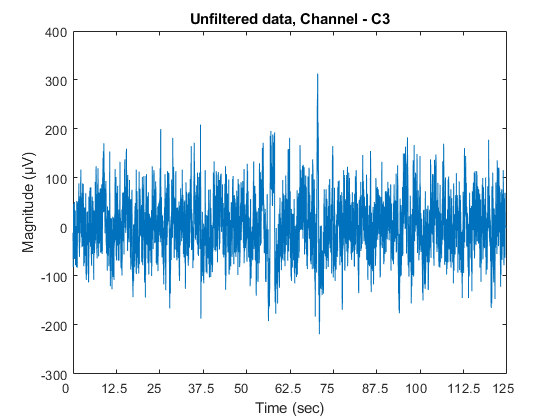

recordT = transpose(record);
plot(recordT(:,9));
xt = get(gca, 'XTick');                               
set(gca, 'XTick', xt, 'XTickLabel', xt/160);
xlabel('Time (sec)');
ylabel('Magnitude (μV)');
title('Unfiltered data, Channel - C3');

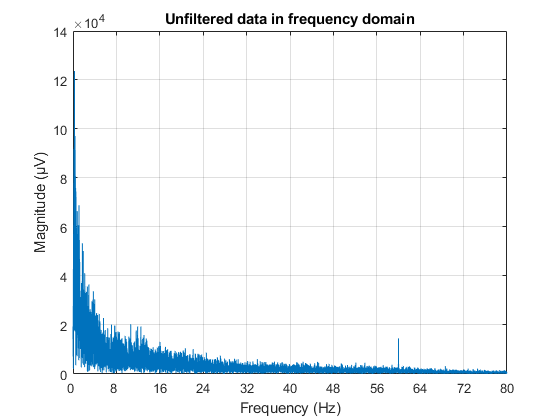

recordT_fft=fft(recordT);
plot(abs(recordT_fft(:,9)));
xlim([0 10000]);
x = get(gca, 'XTick');                               
set(gca, 'XTick', x, 'XTickLabel', x/125);
xlabel('Frequency (Hz)');
ylabel('Magnitude (μV)');
title('Unfiltered data in frequency domain');
grid;

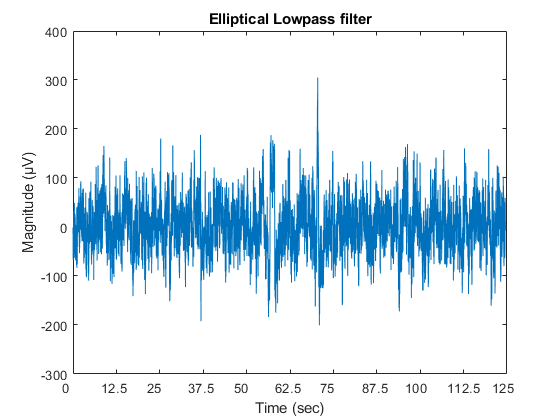

[b,a] =ellip(6,0.5,60,0.625,'low');
out = filter( b, a, recordT);
plot(out(:,9));
xt = get(gca, 'XTick');                               
set(gca, 'XTick', xt, 'XTickLabel', xt/160);
xlabel('Time (sec)');
ylabel('Magnitude (μV)');
title('Elliptical Lowpass filter');

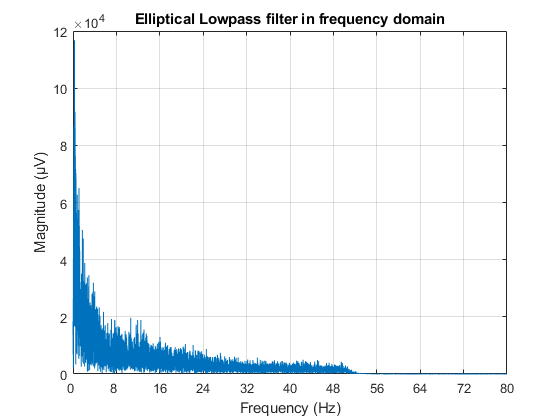

out_fft=fft(out);
plot(abs(out_fft(:,9)));
xlim([0 10000]);
x = get(gca, 'XTick');                               
set(gca, 'XTick', x, 'XTickLabel', x/125);
xlabel('Frequency (Hz)');
ylabel('Magnitude (μV)');
title('Elliptical Lowpass filter in frequency domain');
grid;

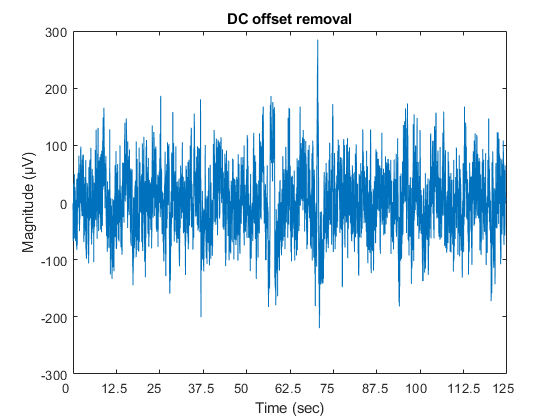

dc1 = dsp.DCBlocker('Algorithm','IIR','Order', 3);
dcout=dc1(out);
plot(dcout(:,9));
xt = get(gca, 'XTick');                               
set(gca, 'XTick', xt, 'XTickLabel', xt/160);
xlabel('Time (sec)');
ylabel('Magnitude (μV)');
title('DC offset removal');

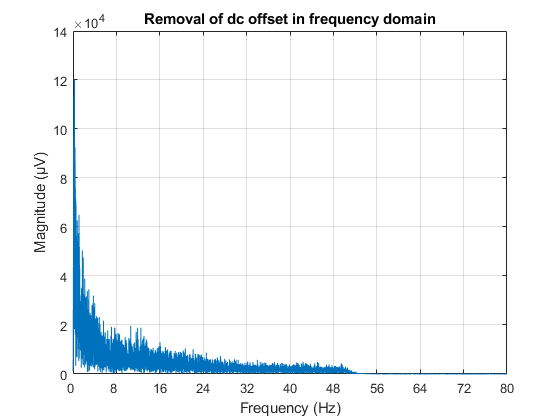

data_fft=fft(dcout);
plot(abs(data_fft(:,9)));
xlim([0 10000]);
x = get(gca, 'XTick');                               
set(gca, 'XTick', x, 'XTickLabel', x/125);
xlabel('Frequency (Hz)');
ylabel('Magnitude (μV)');
title('Removal of dc offset in frequency domain');
grid;

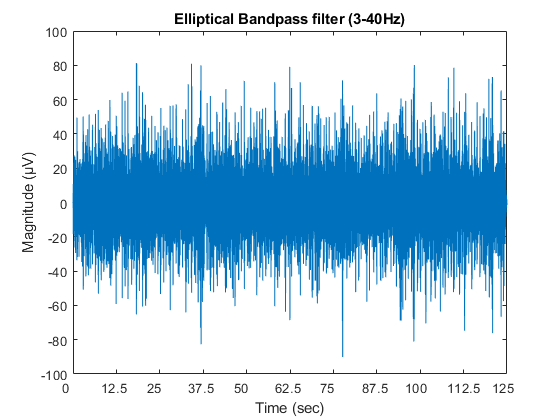

[d,c]=ellip(6,1.5,60,[8,40]/80,'bandpass');
output=filter(d,c,dcout);
plot(output(:,9));
xt = get(gca, 'XTick');                               
set(gca, 'XTick', xt, 'XTickLabel', xt/160);
xlabel('Time (sec)');
ylabel('Magnitude (μV)');
title('Elliptical Bandpass filter (3-40Hz)');

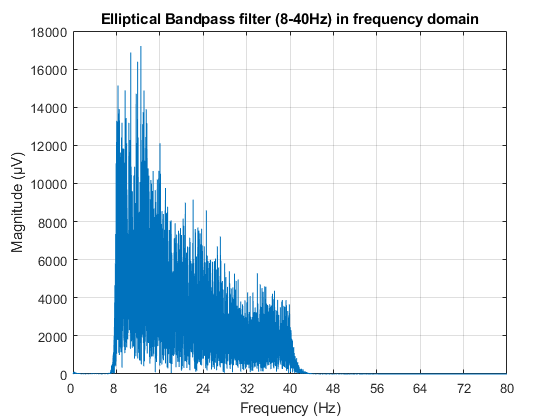

outfft=fft(output);
plot(abs(outfft(:,9)));
xlim([0 10000]);
x = get(gca, 'XTick');                               
set(gca, 'XTick', x, 'XTickLabel', x/125);
xlabel('Frequency (Hz)');
ylabel('Magnitude (μV)');
title("Elliptical Bandpass filter (8-40Hz) in frequency domain");
grid;